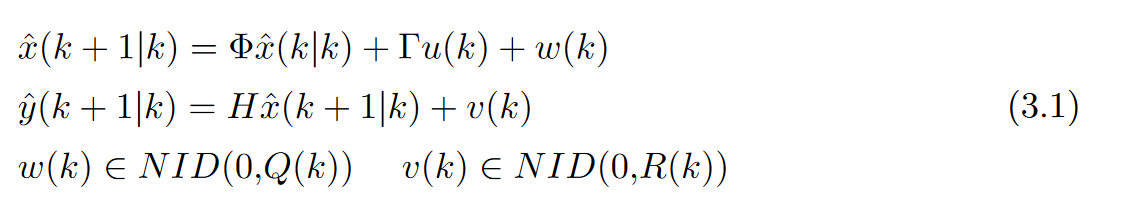

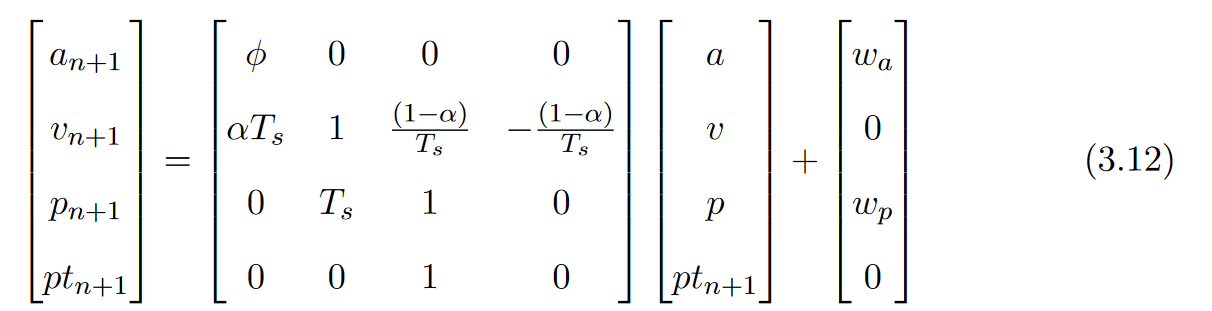

clear
data=load("Move_the_ardunio3"); 

%Model representation: 
phi=0.8;
Ts=0.075; 
alpha=0.1; 
Phi= [phi,0,0,0;alpha*Ts,1,(1-alpha)/Ts,-(1-alpha)/Ts;0,Ts,1,0;0,0,1,0];
H= [1,0,1,0]; 


% Initialising
xh0=[0;0;0;0]; 
P0= eye(4)*0.1; 
R=0.0419^2;
sigma_a=0.0419^2;
sigma_p=0.0419^2;

Q=[sigma_a,0,0,0;0,0,0,0;0,0,sigma_p,0;0,0,0,0]

Q =     0.0018         0         0         0
         0         0         0         0
         0         0    0.0018         0
         0         0         0         0



%Making a few definition before the for loop for the Kalman filter. 
Number_samples=length(data);
Number_states=size(Phi,1);
Number_outputs=size(H,1);

yp= zeros(Number_outputs,Number_samples) % prediction for output p=prediction thereby k|k-1 
ye= zeros(Number_outputs,Number_samples); % prediction for output e=estimation thereby k|k

xe= zeros(Number_states,Number_samples); %estimation of state E for estimation thereby k|k
xp= zeros(Number_states,Number_samples); %prediction for states, p=prediction. 

xhm= xh0; 
yhm= H*xhm;
Pm= P0;




%Initlaxation values for the Kalman filter
xp(:,1)= xh0; 

Unrecognized function or variable 'Number_samples'.

Pp= P0;
% KF
for i= 1:Number_samples
  % Measurement update
  yp(:,i)= H*xp(:,i); %measurements update
  
  %Estimation error:
  Est_error=data(i,2)*9.82-yp(:,i); 
  %Kalman gain:
  K= Pp*H'*inv((H*Pp*H'+R)); 
  %estimation of x: 
  xe(:,i)= xp(:,i)+K*(Est_error); 
  %Covaraince of error: 
  Pe= (eye(3)-K*H)*Pp*(eye(Number_states)-K*H)'+K*R*K';

  % Time update
  xp(:,i+1)= Phi*xe(:,i);
  Pp= Phi*Pe*Phi'+Q;
end


plot(xe(1,:))
title("Acceleration")
plot(xe(2,:))
title("Velocity")
plot(xe(3,:))
title("Position")

clf
data=load("Move_the_ardunio3"); 
hold on 
plot(xe(1,:))
plot(data(:,2)*9.82)
hold off

